# Nonlinear beam experiment

We derive an SSM-reduced model from experimental data for the bending motion of a nonlinear beam. In this experiment, the response of the beam (transmitter) to external excitation induces gravitational forces on a bending beam resonator (receiver). located at a distance (Brack er al [1]). The interaction between transmitter and receiver beams can then be studied to estimate the gravitational constant between the two objects. As such, accurate modeling of the beam becomes crucial. The forced response curves computed around the slowest bending modes of the transmitter beam reveal clear nonlinear behavior.

Here we seek to construct a nonlinear 2D SSM-reduced model of the transmitter beam from decaying trajectory data.

[1] T. Brack, B. Zybach, F. Balabdaoui, S. Kaufmann, F. Palmegiano, J.-C. Tomasina, S. Blunier, D. Scheiwiller, J. Fankhauser and J, Dual. Dynamic measurement of gravitational coupling between resonating beams in the hertz regime. Nat. Phys. 18, 952-957 (2022). 

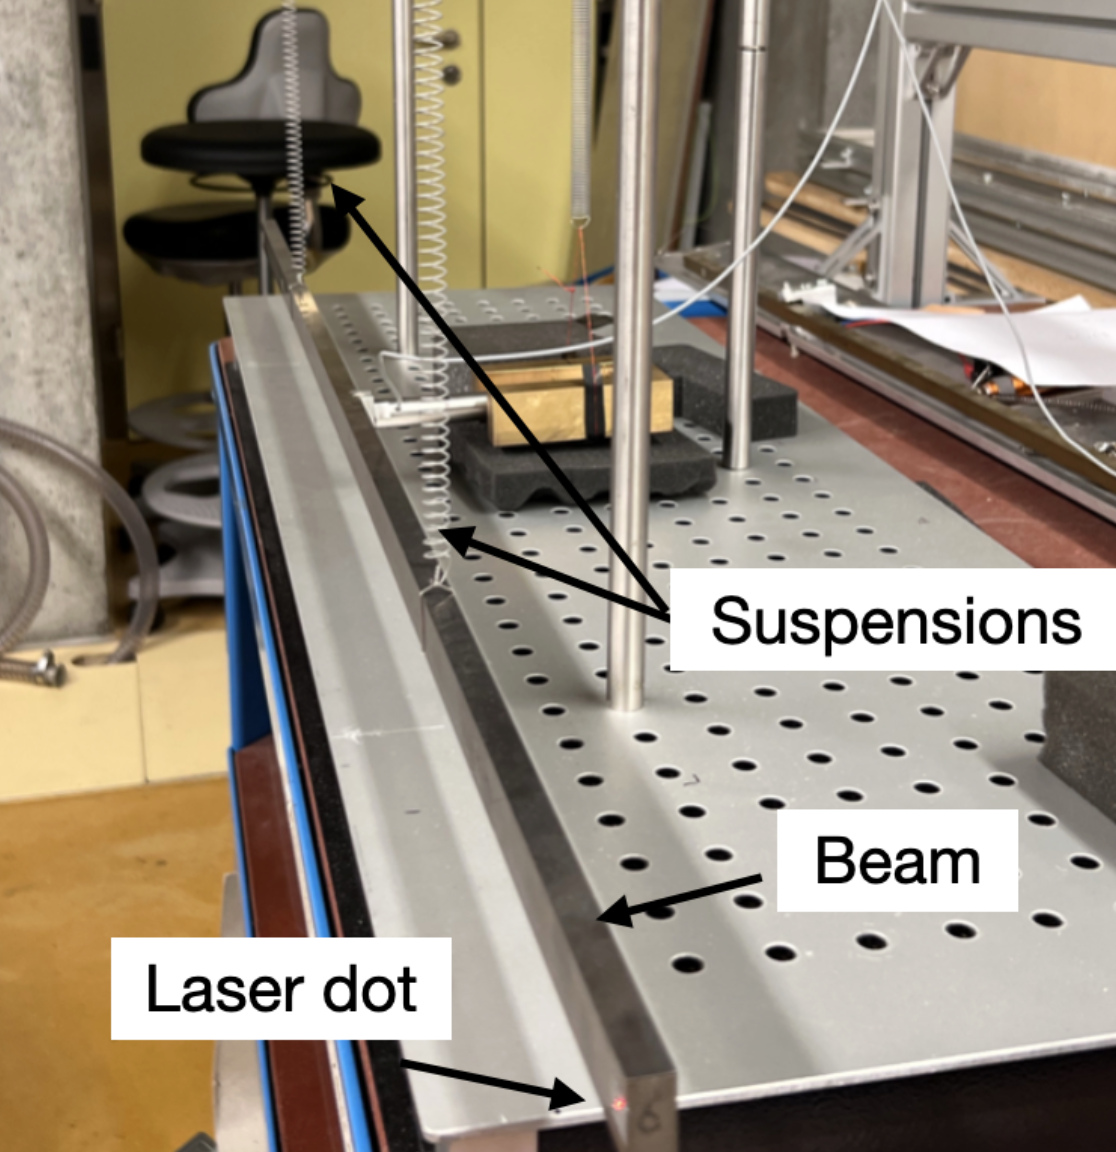

clearvars
close all

## Data extraction

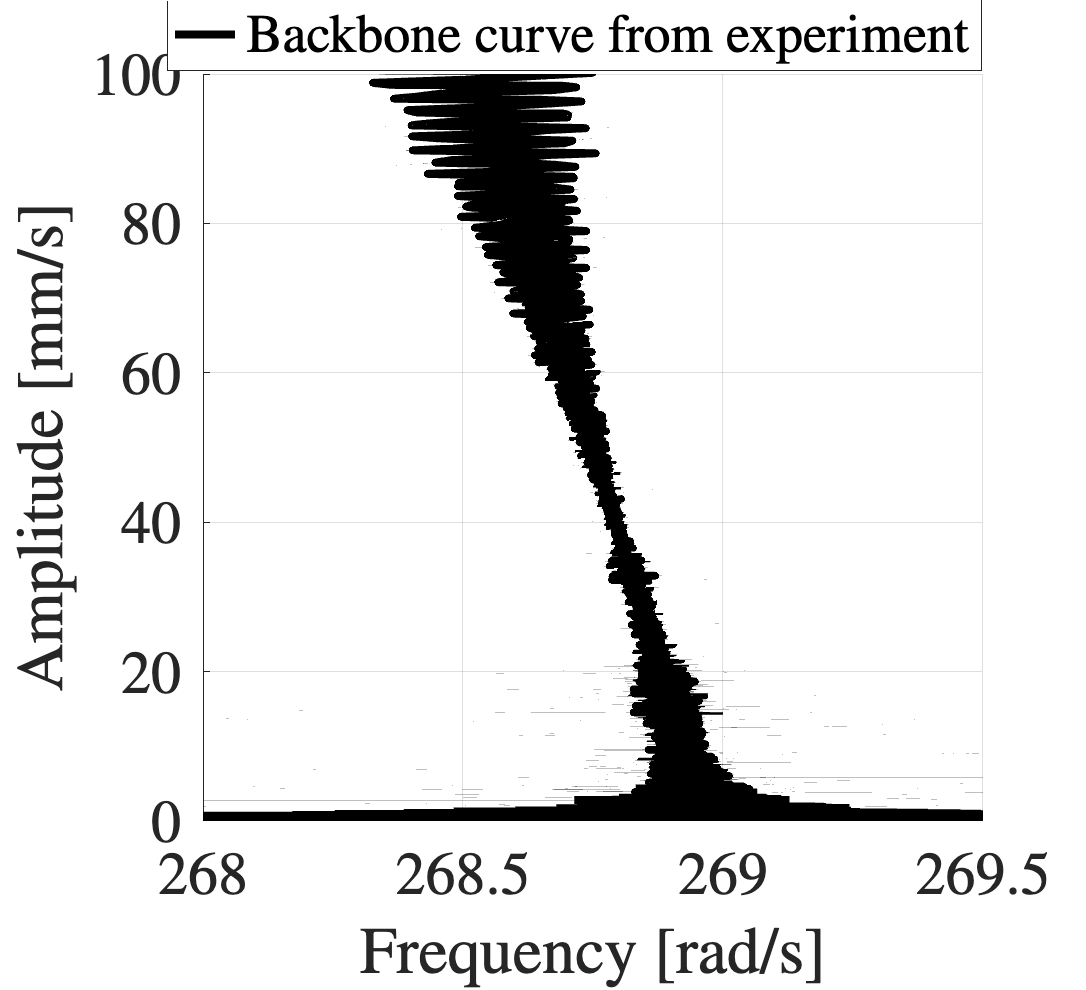

load('nonlinear_beam_experiments/decaying_data.mat')

fact_amp = 50*4;
signal_decay = fact_amp * dev4955.scopes.wave{1,1}.wave;
signal_net = signal_decay(round(length(signal_decay)*0.03):round(length(signal_decay)*0.7));
dt = dev4955.scopes.wave{1,1}.dt;
t_vect = linspace(0,length(signal_net)*dt, length(signal_net));

dt = diff(t_vect(1:2));

% backbone curve of experimental data 
index = length(t_vect);
kmean = 1;
Y = signal_net;
X = [ones(length(signal_net),1) t_vect.'];
B = X\Y;
signal_centered = signal_net - B(1);

signal_filtered = fliplr(bandpass(fliplr(signal_centered),[30 250],1/dt));
[amp,freq,damp,time] = PFFk(t_vect(1:index),signal_filtered(1:index),kmean);

f = figure;
f.Position = [406,328,590,538];
hold on 
grid on 
plot(2*pi*freq, amp,'color','k','LineWidth',4,'DisplayName','Backbone curve from experiment')

xlim([268 269.5])
ylim([0 100])
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('Amplitude [mm/s]','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelinterpreter','latex')
legend('location','N','Position',[0.163388475321107,0.931412638341626,0.731526778916181,0.067657993628633],'Interpreter','latex')

## Oblique projection and delay embedding 

We compute the linear oblique projection that best approximates the direction of the fast subspace from data. Obliquely projected coordinates serve as the reduced coordinates for the SSM parametrization, when the linear part of the dynamical system is non-normal. This procedure is strictly valid for oscillatory systems. The linear approximation of the projection is most accurate when computed from the linear regime of the data. In the suboptimal case when the linear regime of the data is unknown, the oblique projection is automatically computed across the entire data range.

Set $\texttt{oblique\_projection = false}$ in order to apply the standard normal projection. 

lim = 5e-9;
SSMDim = 2;

overEmbed = 1;
ShiftStep = 1;

oblique_projection = true;

xData = cell(1,2);
xData{1,1} = t_vect;
xData{1,2} = transpose(signal_filtered);

indStartTime = regimeLinear(xData,lim);

[yData, P, V_trunc_slow,data_non_projected,data_non_projected_trunc] = obliqueProjection(xData,indStartTime,SSMDim, overEmbed, ShiftStep, 'flag_end',2,'oblique_projection',oblique_projection);

The 6 embedding coordinates consist of the measured state and its 5 time-delayed measurements.
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          13          5.99424                         0.139
     1          91          3.05776         31.951           5.19  
     2         117          2.87541            0.1           6.67  
     3         143          2.51146       0.256412           0.55  
     4         156           2.4991              1          0.385  
     5         169          2.49361              1          0.322  
     6         182          2.48624              1          0.255  
     7         195          2.43448              1           1.07  
     8         247          2.43148     0.00435573           1.29  
     9         273          2.42697       0.308996           1.44  
    10         286          2.38246              1           1.05  
    11         299    

The function $\texttt{obliqueProjection}$ also arranges the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

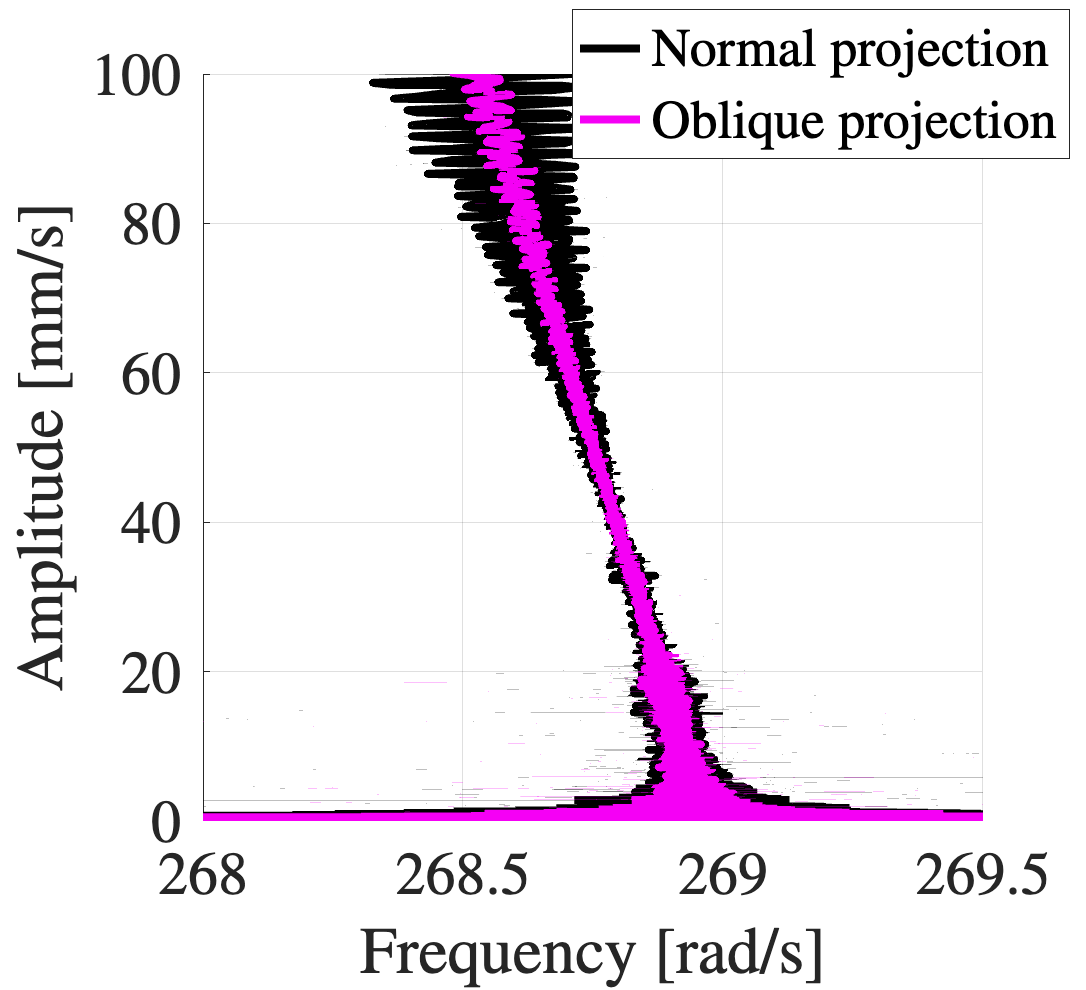

xOutput = @(x) x(1,:);
kmean = 1;       
[amp_z,freq_z,damp_z,time_z] = PFFk(t_vect,xOutput(yData{1,2}),kmean);

f = figure;
f.Position = [406,328,590,538];
hold on 
grid on 
plot(2*pi*freq, amp,'-k','LineWidth',4,'DisplayName','Normal projection')
plot(2*pi*freq_z, amp_z,'color',[0.96,0.00,0.96],'LineWidth',4,'DisplayName','Oblique projection')
xlim([268 269.5])
ylim([0 100])
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('Amplitude [mm/s]','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelinterpreter','latex')
legend('location','N','Position',[0.524405424473649,0.845512892870875,0.463730168746689,0.139617218653288],'Interpreter','latex')

## SSM model reduction

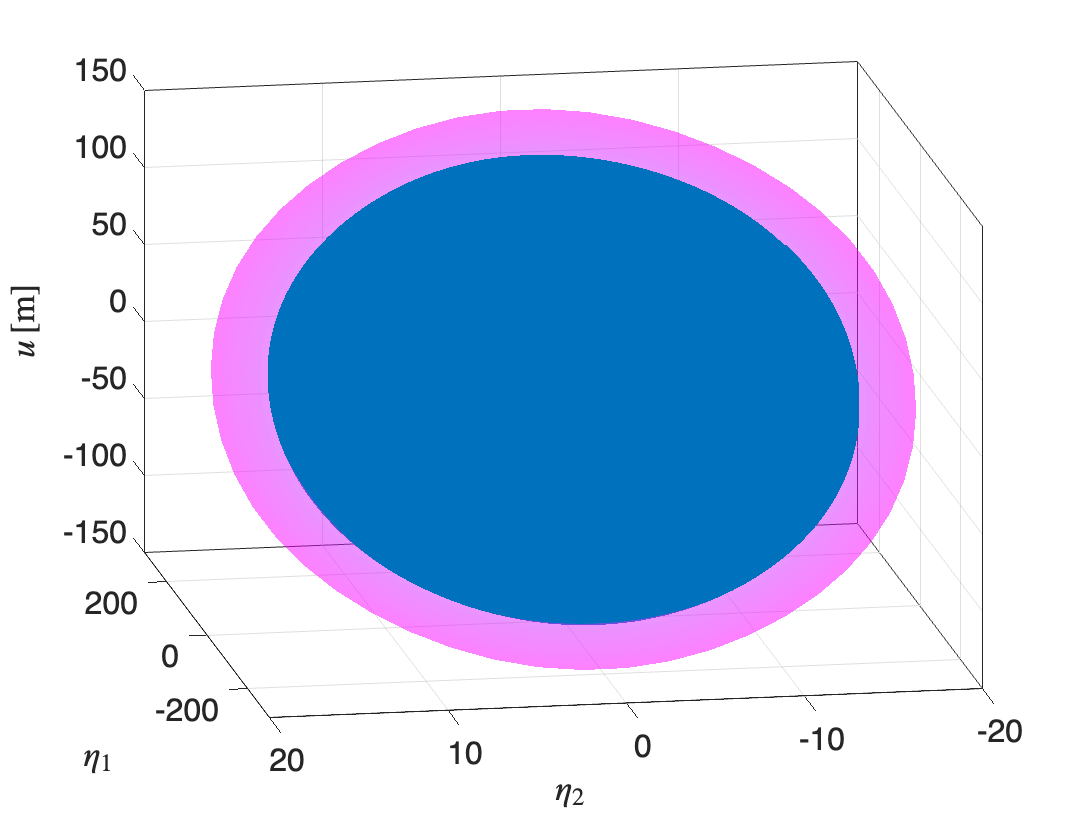

endTime = yData{1,1}(end);
sliceInt = [1, endTime];
yDataTrunc = sliceTrajectories(yData, sliceInt);

indTrain = 1;
indTest = 1;

% manifold parametrization
SSMOrder = 7;

% compute the reduced coordinates as the oblique projection of the
% coordinates in the full observable space onto the slow subspace 

[IMInfo, ~, ~] = IMGeometry(yDataTrunc(indTrain,:), SSMDim, 1,'V_e',V_trunc_slow);
SSMChart_P = @(x) IMInfo.parametrization.tangentSpaceAtOrigin'*P*x;
etaData = projectTrajectories(IMInfo, yData);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

yData_original = data_non_projected;
yData_original_Trunc = sliceTrajectories(yData_original, sliceInt);
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData_original_Trunc(indTrain,:), SSMDim, SSMOrder, 'reducedCoordinates', etaDataTrunc(indTrain,:));
IMInfo.chart.map = SSMChart_P;

plotSSMWithTrajectories(IMInfo, 1, yData_original_Trunc(indTrain,:))
view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1        0.0252225                          1.49
     1           5         0.022077     0.00156537              1  
     2           6        0.0198795              1          0.863  
     3           7        0.0129995              1          0.285  
     4           8        0.0127888              1          0.271  
     5           9        0.0120057              1          0.261  
     6          10        0.0118407              1          0.297  
     7          11        0.0112694              1          0.234  
     8          12        0.0111049              1           0.16  
     9          13        0.0110245              1          0.142  
    10          14        0.0109665              1          0.116  
    11          15

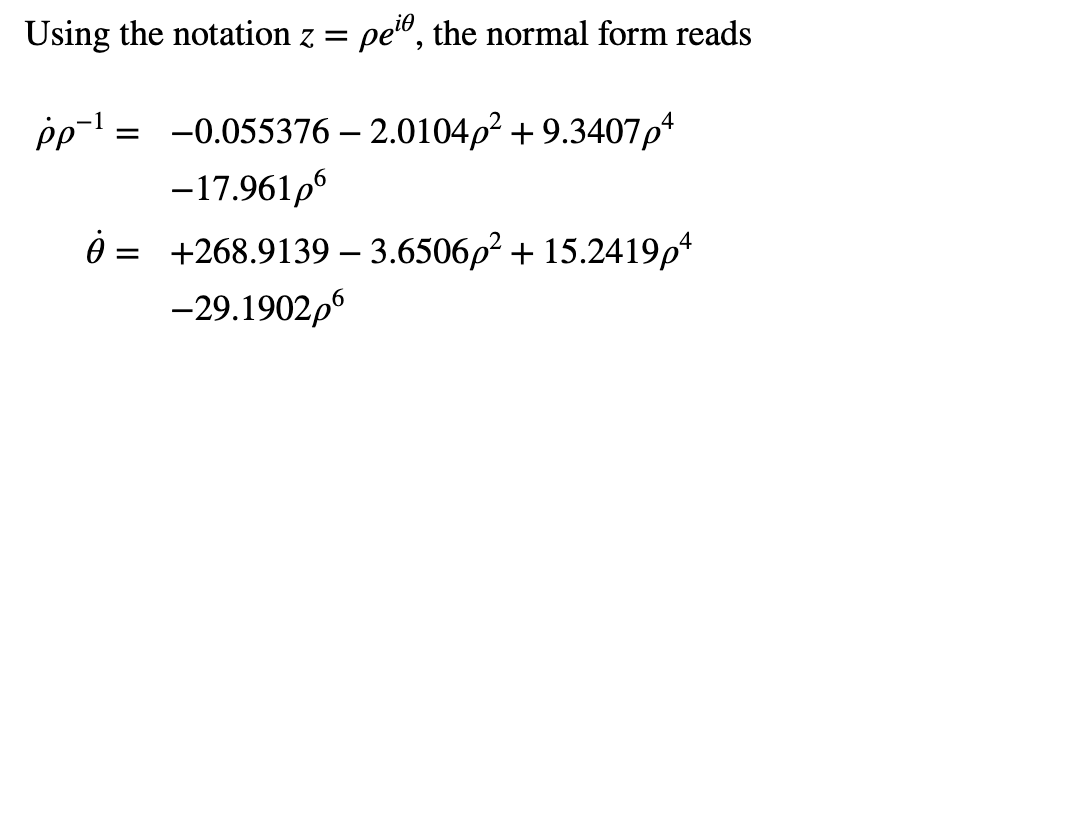


% manifold reduced dynamics 
ROMOrder = 7;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform');

## Backbone curves

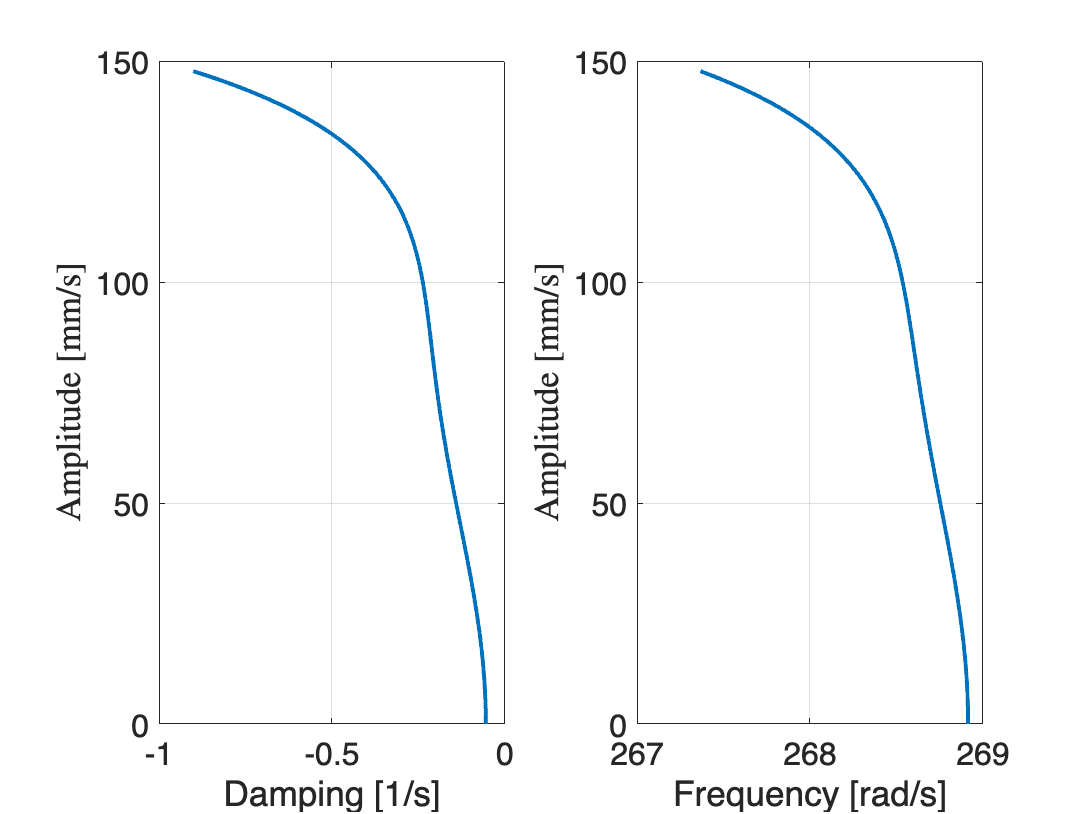

zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
rhoCal = abs(zData{indTest(1),2}(1,1));
amplitudeFunction = @(x) x(1,:);

BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoCal);
subplot(121); ylabel('Amplitude [mm/s]','Interpreter','latex')
subplot(122); ylabel('Amplitude [mm/s]','Interpreter','latex')

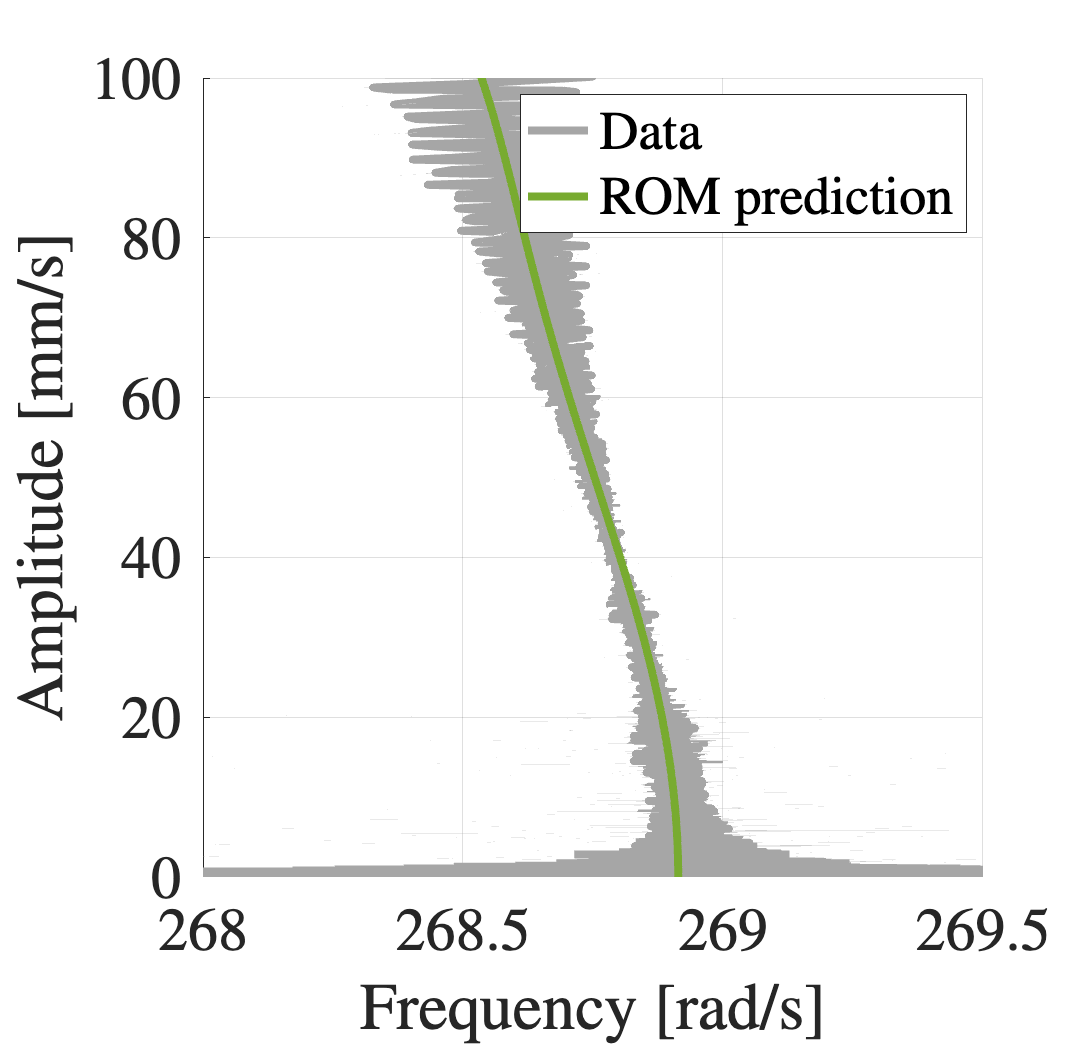


f = figure;
f.Position = [705,132,641,617];
hold on 
grid on 
plot(2*pi*freq, amp,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Data')
plot(BBCInfo.frequency, BBCInfo.amplitude,'color',[0.47,0.67,0.19],'LineWidth',4,'Displayname','ROM prediction')
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('Amplitude [mm/s]','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelInterpreter','latex')
ylim([0 100])
xlim([268 269.5])
legend('location','NE','Interpreter','latex')

## Forced response curves

f = figure;
f.Position = [705,132,641,617];
hold on 
grid on 
plot(2*pi*freq,amp,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Data')
plot(BBCInfo.frequency(BBCInfo.amplitude<110), BBCInfo.amplitude(BBCInfo.amplitude<110),'color',[0.39,0.83,0.07],'LineWidth',4,'Displayname','ROM prediction')
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('Amplitude [mm/s]','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelinterpreter','latex','Position',[0.158264687278054,0.136904373539905,0.613966201957516,0.788095626460096])
ylim([0 100])
xlim([268 269.5])
legend('location','NE','Interpreter','latex','Position',[0.5231,0.6549,0.466,0.2723]);

% extract data from forced experiment
load('nonlinear_beam_experiments/forced_data.mat');

X_data = forced_data.Results.X1_avg__V_.data;
Y_data = forced_data.Results.Y1_avg__V_.data;
freq_FRC = forced_data.Results.Frequency_of_MFLI_avg__Hz_.data;
% compute the amplitude
R_data = sqrt(X_data.^2 + Y_data.^2);
% transform to physical quantities
R_data_scope = sqrt(2) * R_data;
range = 10; % property of the scope: do not change
ampl_FRC = 4 * range * R_data_scope; % property of the scope: do not change 
phase_data = atan2(Y_data,X_data);


% from the model 

omegaSpan_bottom = 268.3;
omegaSpan_top = 269.1;
% amplitudeCal = [39 55 71 93];
% amplitudeCal = [40.8 59.58 76.44 99.84]; % DMD
% amplitudeCal = [32.41 47.38 60.97 79.87];
% amplitudeCal = [36.24, 52.71, 68, 88.84];
amplitudeCal = [38.41, 56.00, 71.95, 93.83];
forcingSpan = zeros(1,length(amplitudeCal));
for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingSpan(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos);
end
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


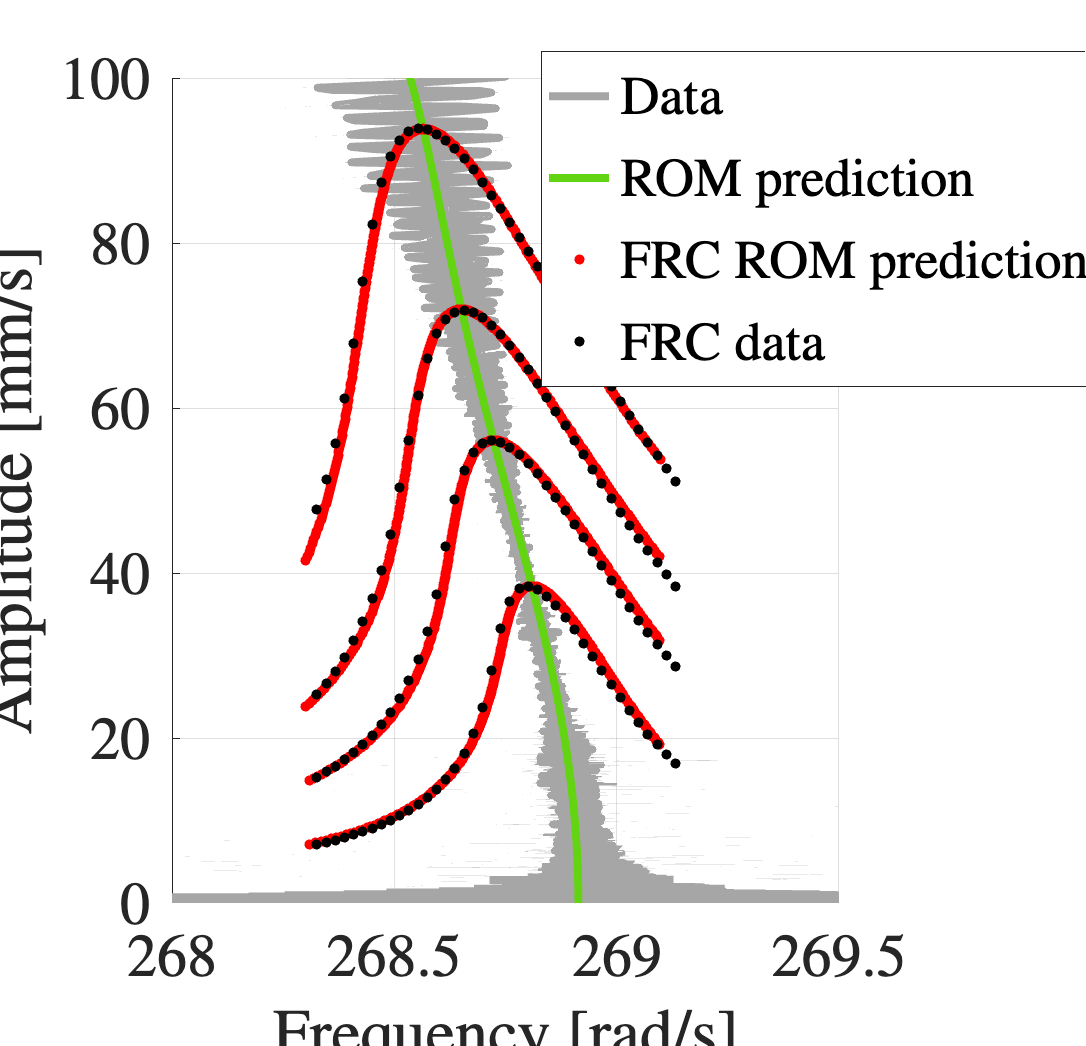

FRCData = analyticalFRC(IMInfoF,RDInfoF,forcingSpan,amplitudeFunction);

for ii = 1:length(amplitudeCal)
    
    forced_freq = FRCData.(['F' num2str(ii)]).Freq(:);
    forced_amp = FRCData.(['F' num2str(ii)]).Amp(:);
    
    index_plot = find(forced_freq>=omegaSpan_bottom & forced_freq<=omegaSpan_top);
    forced_freq_plot = forced_freq(index_plot);
    forced_amp_plot = forced_amp(index_plot);
    
    if ii == 1
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'DisplayName','FRC ROM prediction')
    else
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'HandleVisibility','off')
    end

end

[amplitude, index] = unique(forced_data.Data.Amplitude_of_Excitation__V_.data);
% [freq_FRC_proj, ampl_FRC_proj] = project_FRC(freq_FRC, ampl_FRC,SSMDim,overEmbed,ShiftStep,P_min);
ampl_FRC_proj = ampl_FRC;
freq_FRC_proj = 2*pi*freq_FRC;
n_length = length(freq_FRC)/length(amplitude);
plot(freq_FRC_proj(1:n_length), ampl_FRC_proj(1:n_length),'k.','LineWidth',1,'MarkerSize',15,'DisplayName','FRC data');
plot(freq_FRC_proj(n_length+1:2*n_length), ampl_FRC_proj(n_length+1:2*n_length),'k.','LineWidth',1,'MarkerSize',15,'HandleVisibility','off');
plot(freq_FRC_proj(2*n_length+1:3*n_length), ampl_FRC_proj(2*n_length+1:3*n_length),'k.','LineWidth',1,'MarkerSize',15,'HandleVisibility','off');
plot(freq_FRC_proj(3*n_length+1:4*n_length), ampl_FRC_proj(3*n_length+1:4*n_length),'k.','LineWidth',1,'MarkerSize',15,'HandleVisibility','off');